# Tutorial04 Simulating and Imaging Randomly Diffusing Molecules

#### Notes

Note. Save all my code. They will be reused and build on each other.

Objective: To be more famiiar with Matrix multiplications through a variation of a random walk.

2. Simulating a Random Walk in 1D

1.. Initialize two matrices

% Parameters
L = 500

L = 500

n_particle = 500

n_particle = 500

n_kicks = 10000

n_kicks = 10000


f = zeros(n_kicks, n_particle);
x = zeros(n_kicks, n_particle);

2.. Assign the initial particle positions in f(1, :) such that the n_p particles are uniformly disributed across the Universe.

% Initially did
% f(1,:) = length*rand(1, n_particle)

% After reaching step 5, for convenience, decided to refer to the solution.
f(1,:) = randperm(L)

f =    144   226    89   287    65   115   339   488   164   341    71   408   105    48    67    73   180   282   467   257   216   445   199    82   237     5   459   329   162    88   413   376   244   328   179   156   486   346   151   118    98   135   390   336   403   412   324   281   201    10
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

3.. Store displacement of each kick.

Received help from solution doc.

% Assign kicks at each time step.
f(2:end,:) = randn(n_kicks-1, n_particle)

f =   144.0000  226.0000   89.0000  287.0000   65.0000  115.0000  339.0000  488.0000  164.0000  341.0000   71.0000  408.0000  105.0000   48.0000   67.0000   73.0000  180.0000  282.0000  467.0000  257.0000  216.0000  445.0000  199.0000   82.0000  237.0000    5.0000  459.0000  329.0000  162.0000   88.0000  413.0000  376.0000  244.0000  328.0000  179.0000  156.0000  486.0000  346.0000  151.0000  118.0000   98.0000  135.0000  390.0000  336.0000  403.0000  412.0000  324.0000  281.0000  201.0000   10.0000
   -1.6293   -1.5477   -0.9680   -1.1056   -0.1777    0.1181   -0.5911   -0.8965   -0.9878    0.5602    0.8127    1.7266   -0.3319   -0.0416   -0.5820   -0.3790    0.5045    0.3001    0.3542   -0.6401    0.4891    1.2934   -0.4161   -1.0733    0.4200   -0.6488   -0.5357   -1.1479   -0.0523    1.4598    1.7982   -0.9004   -0.5851   -0.9295   -0.9939    0.3764   -0.2575   -0.6725    0.8937   -0.9455   -0.5043   -1.1604   -1.3384    0.1128   -0.7760   -0.6219    0.5365   -0.2240   -0.0688   -1

Note. Difference between **rand** and **randn**.

**rand**: uniformly distributed random numbers. Returns random #s between 0 and 1 from uniform distribution.

**randn**: normally(Gaussian) distributed random numbers. Returns random #s of mean 0 and variance 1.

4.. Assign x to the particle trajectories. Use **cumsum** and mod.

% help cumsum
% stepx = cumsum(-1+2*stepx)
x = cumsum(f)

x =   144.0000  226.0000   89.0000  287.0000   65.0000  115.0000  339.0000  488.0000  164.0000  341.0000   71.0000  408.0000  105.0000   48.0000   67.0000   73.0000  180.0000  282.0000  467.0000  257.0000  216.0000  445.0000  199.0000   82.0000  237.0000    5.0000  459.0000  329.0000  162.0000   88.0000  413.0000  376.0000  244.0000  328.0000  179.0000  156.0000  486.0000  346.0000  151.0000  118.0000   98.0000  135.0000  390.0000  336.0000  403.0000  412.0000  324.0000  281.0000  201.0000   10.0000
  142.3707  224.4523   88.0320  285.8944   64.8223  115.1181  338.4089  487.1035  163.0122  341.5602   71.8127  409.7266  104.6681   47.9584   66.4180   72.6210  180.5045  282.3001  467.3542  256.3599  216.4891  446.2934  198.5839   80.9267  237.4200    4.3512  458.4643  327.8521  161.9477   89.4598  414.7982  375.0996  243.4149  327.0705  178.0061  156.3764  485.7425  345.3275  151.8937  117.0545   97.4957  133.8396  388.6616  336.1128  402.2240  411.3781  324.5365  280.7760  200.9312    8

x = mod(x, 500)

x =   144.0000  226.0000   89.0000  287.0000   65.0000  115.0000  339.0000  488.0000  164.0000  341.0000   71.0000  408.0000  105.0000   48.0000   67.0000   73.0000  180.0000  282.0000  467.0000  257.0000  216.0000  445.0000  199.0000   82.0000  237.0000    5.0000  459.0000  329.0000  162.0000   88.0000  413.0000  376.0000  244.0000  328.0000  179.0000  156.0000  486.0000  346.0000  151.0000  118.0000   98.0000  135.0000  390.0000  336.0000  403.0000  412.0000  324.0000  281.0000  201.0000   10.0000
  142.3707  224.4523   88.0320  285.8944   64.8223  115.1181  338.4089  487.1035  163.0122  341.5602   71.8127  409.7266  104.6681   47.9584   66.4180   72.6210  180.5045  282.3001  467.3542  256.3599  216.4891  446.2934  198.5839   80.9267  237.4200    4.3512  458.4643  327.8521  161.9477   89.4598  414.7982  375.0996  243.4149  327.0705  178.0061  156.3764  485.7425  345.3275  151.8937  117.0545   97.4957  133.8396  388.6616  336.1128  402.2240  411.3781  324.5365  280.7760  200.9312    8

**cumsum**: cumulative sum of elements. Check documentation how it works for a matrix.

Sample Code

`Cumsum of each column`

`A = [1 4 7; 2 5 8; 3 6 9]`

`A = `*3×3*

`     1     4     7`

`     2     5     8`

`     3     6     9`

`B = cumsum(A)`

`B = ``3×3`

`     1     4     7`

`     3     9    15`

`     6    15    24`

`Cumsum of each row`

`A = [1 3 5; 2 4 6]`

`A = ``2×3`

`     1     3     5`

`     2     4     6`

`B = cumsum(A,2)`

`B = ``2×3`

`     1     4     9`

`     2     6    12`

**mod**: Takes mod. 

Sample code.

q = [0:10] 

mod(q,5)

mod(q,4)

Q = [0:10;0:10;0:10] 

mod(Q,5) 

mod(Q,2)

Here, mod is used to ensure the particles stay in the universe.

5.. Visualizing particle trajectories by creating an *image*.

I(x,t). corresponds to the # of particles at location x at time t. 

Image: a matrix that represents the grid of pixels, whose entires contain some info about those pixels - here, it's intensity. c.f. The higher the count of a pixel, the brighter it'll be.

% first, use ceiling to discretize x.
x = ceil(x)

x =    144   226    89   287    65   115   339   488   164   341    71   408   105    48    67    73   180   282   467   257   216   445   199    82   237     5   459   329   162    88   413   376   244   328   179   156   486   346   151   118    98   135   390   336   403   412   324   281   201    10
   143   225    89   286    65   116   339   488   164   342    72   410   105    48    67    73   181   283   468   257   217   447   199    81   238     5   459   328   162    90   415   376   244   328   179   157   486   346   152   118    98   134   389   337   403   412   325   281   201     9
   142   225    88   286    64   115   337   488   164   342    73   411   106    47    67    72   182   281   468   256   215   446   197    81   238     5   459   328   164    89   414   375   245   328   178   158   486   346   153   119    96   134   388   337   402   412   324   281   203     8
   142   227    88   287    66   114   338   488   165   341    72   412   103    47    68   


% create image to store result.
% initialize image
I = zeros(L, n_kicks)

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% for each number from 1 to 500, count the occurence and store in the matrix.
for n = 1:n_kicks
    location_ranges = 1:500;
    [counts, ind] = histc(x(n, :), location_ranges);
    % transpose(counts)
    I(:, n) = transpose(counts);  % can use " counts.' "
end


% Below is an alternative from sample solution.
% Create the image I(x,t) by counting the # of particles at each time
% at all positions using hist.
%for n = 1:n_kicks  % correct
%    I(:, n) = hist(x(n, :), n_particle);
%end

I

I =      1     2     0     1     0     0     1     0     2     0     2     2     0     2     0     0     1     1     1     1     0     1     0     3     2     2     3     0     1     3     0     1     0     0     0     3     0     3     1     1     0     0     1     2     0     2     1     1     1     1
     1     0     0     1     1     1     0     2     0     1     0     1     2     0     0     1     1     1     1     1     1     0     0     0     0     1     1     0     1     1     2     0     1     2     1     1     4     1     3     1     0     1     2     2     4     3     2     0     0     0
     1     1     1     0     1     1     2     1     1     1     2     1     1     1     1     0     1     0     1     1     2     1     0     0     1     1     0     2     1     0     2     3     2     2     0     0     1     2     2     2     4     2     2     1     0     1     1     3     1     2
     1     1     1     2     1     1     2     2     2     1     0     0     0     0     0   

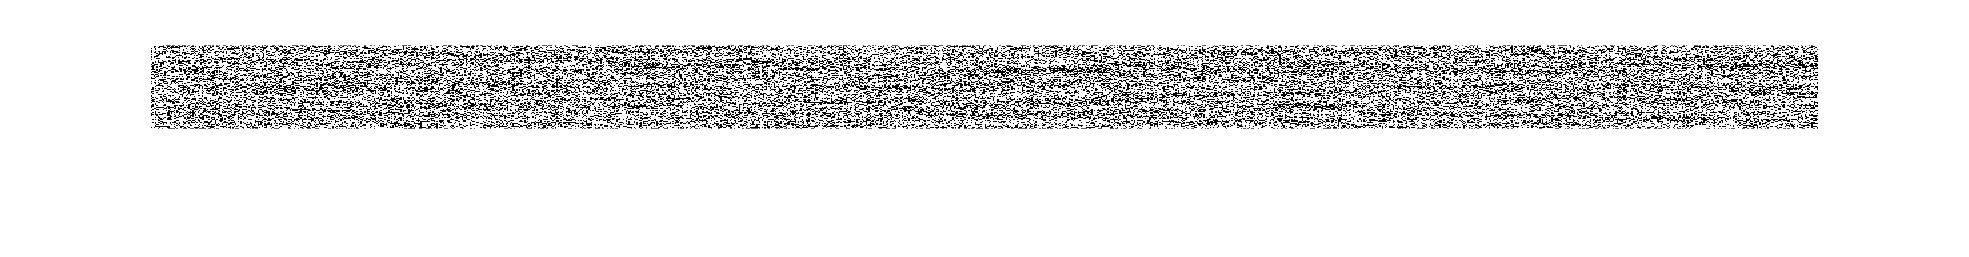

%groupcounts(x)

imshow(I)

Choosing subsection of the matrix and showing it.

%figure
%I_section = I(:, 4500:5500,[])
% Correction comment: my initial range was 3:950, which was too wide.
imshow(I(:,4500:5500),[])

figure % create figure window
imshow(I(:,4500:5500),[]);
xlabel(['time']),ylabel(['position']) 

6.. Calculate the variance in positions sampled by each particle.

% var_particles = var(transpose(I))

% Correction:
variance_x = zeros(1, n_particle)
for i = 1:n_particle
    variance_x(i) = var(x(:, i));
end

% Avg value for variance over all particles:
avg_variance = mean(variance_x)

Correction/Solution: Expected variance is n_kicksd*variance for 1 step = 10000*1 = 10000. This is pretty close to the calculated value.

% Plot particle # vs variance
figure
plot(1:n_particle, variance_x);
% xlabel(['Particle number']),ylabel(['Variance']); 


7. Define the deffusion coefficient as D = var/(2*N_kicks). Calculate D.

D = avg_variance/(2*n_kicks)

Correction/Solution: Expected value based on expected avg_variance would be 10000/(2*10000) = 0.5. The result was D = 0.4718, so they are pretty close.

`8.. Calculate, approximately, how many pixels - h - will a protein molecule diffusion (in 2D) in a given camera exposure time of 2ms/frame.`

% 100um^2/s * (1 pixel/ 0.4um) * (2 ms / frame)
% 2ms = 2000
h = 100*(1/0.4)*2000

Answer: 500000 pixels.

`Correction: Did not know that protein diffuses according to r^2 = 4Dt.`

`r is the distance diffused (in um in our case.)`

D = 100; % um^2/s, diffusion coefficient.
dx = 0.4; % um/pixel, magnification.
exposureTime = 0.002 % seconds

r = sqrt(4*D*exposureTime); % um. Using r^2 = 4Dt. 
numPixls = r/dx; % result: numPixels = 2.2361